## (a)

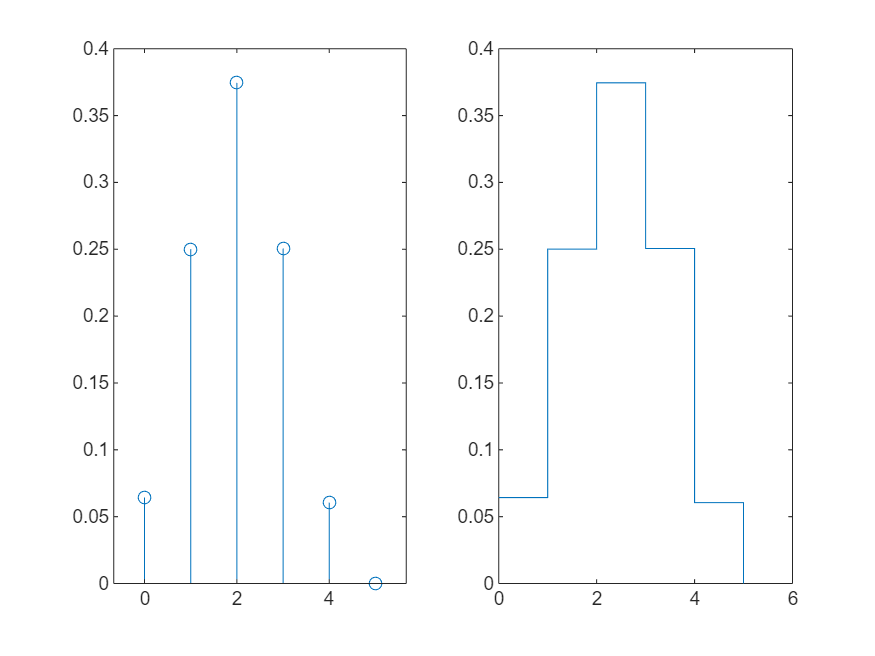

N =10000;

exp = rand(4,N) <= 0.5;
n = sum(exp);

X = 0:5;
fx = zeros(1,5);

for i = X
    fx(i+1) = sum(n==i)/N;
end

figure;

subplot(1,2,1);
stem(X,fx)
subplot(1,2,2);
stairs(X,fx)

## (b)

esp = 0;

for i=0:4
    esp = esp + (i * fx(i+1));
end
esp

esp = 1.9929

v = 0;

for i =0:4
    v = v + (pow2(i) * fx(i+1));
end
v1 = esp^2;
va = v - v1

va = 1.0636

desvio = sqrt(va)

desvio = 1.0313

## (c) Distribuição Binomial, No caderno

## (d)

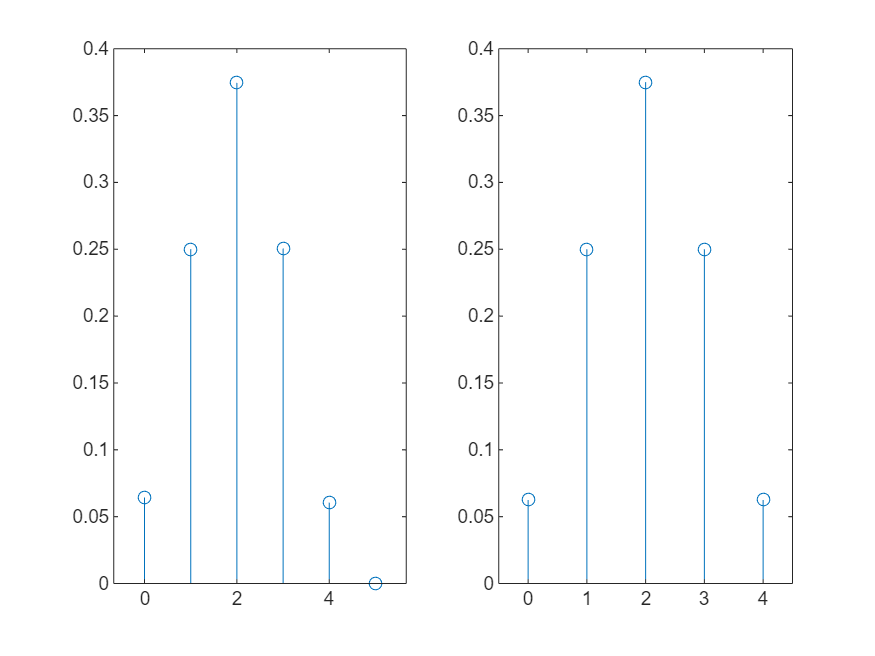

n = 4;
p = 0.5;
pX = zeros(1,5);

for i = 1:5
    k = i -1;
    pX(i) = factorial(n)/(factorial(k)*factorial(n-k)) * p^k * (1-p)^(n-k);
end

x = 0:4;
stem(x,pX);
axis([-0.5 4.5 0 0.4])

## (e)

esp = 0;
for i=0:4
    esp = esp + (i * fx(i+1));
end
esp

esp = 1.9929

## (fi)

p = sum(pX(x >= 2))

p = 0.6875

## (fii)

p = sum(pX(x <= 1))

p = 0.3125

## (fiii)

p = sum(pX(x >= 1 & x <= 3))

p = 0.8750